Para cada frame:

### Cuesta abajo

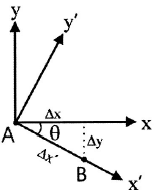

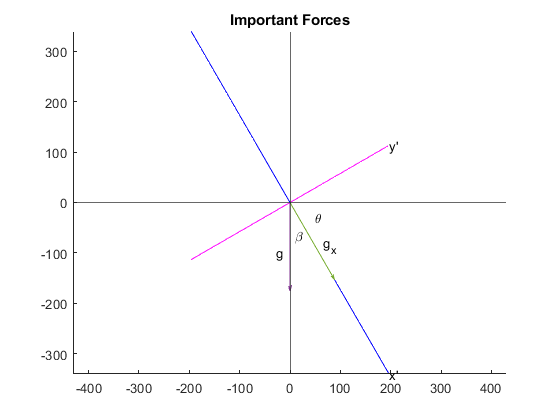

figure;
theta = 30;
gravity = 9.81;
mass = 20;

weight = gravity * mass;

X = linspace(-weight, weight);
y_prime_line = X .* tand(theta);
x_prime_line = X .* -1/tand(theta);
x_prime_line_f = @(x) x .* -1/tand(theta);

hold on;
plot(0, 5, "r-");
plot(X, y_prime_line, "Color", "magenta");
plot(X, x_prime_line, "Color", "blue");

quiver(0, 0, 0, -weight);
quiver(0, 0, weight * sind(theta), -weight * cosd(theta));

text(-weight/7, -weight/2, "g");
text(weight * sind(theta) / 1.5, -weight * cosd(theta) / 2, "g_{x}");

text(X(end), y_prime_line(end), "y'");
text(X(end), x_prime_line(end), "x'");
text(weight/4, -weight/7, sprintf("\\theta"));
text(weight/20, -weight/3, sprintf("\\beta"));
yline(0);
xline(0);

title("Important Forces");
axis equal;

$\theta =\arctan \left(f^{\prime } \left(x\_\textrm{pos}\right)\right)$ ver abajo para x_pos


$$\beta =90-\textrm{abs}\left(\theta \right)$$



$$g_x =-\textrm{sign}\left(\theta \right)*g*\cos \left(\beta \right)$$



$$\Delta x^{\prime } =v*\textrm{dt}+\frac{1}{2}*g_x *{\textrm{dt}}^2$$


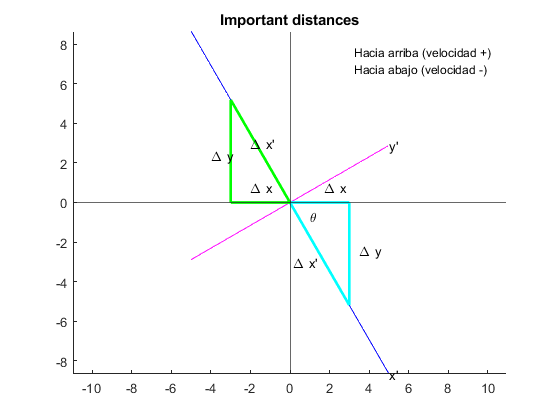

figure;
theta = 30;

X = linspace(-5, 5);
y_prime_line = X .* tand(theta);
x_prime_line = X .* -1/tand(theta);
x_prime_line_f = @(x) x .* -1/tand(theta);

hold on;
plot(0, 5, "r-");
plot(X, y_prime_line, "Color", "magenta");
plot(X, x_prime_line, "Color", "blue");

plot([0 3], [0 x_prime_line_f(3)], "Color", "cyan", "LineWidth", 2);
plot([0 3], [0 0], "Color", "cyan", "LineWidth", 2);
plot([3 3], [0 x_prime_line_f(3)], "Color", "cyan", "LineWidth", 2);

plot([0 -3], [0 x_prime_line_f(-3)], "Color", "green", "LineWidth", 2);
plot([0 -3], [0 0], "Color", "green", "LineWidth", 2);
plot([-3 -3], [0 x_prime_line_f(-3)], "Color", "green", "LineWidth", 2);

text(0.15, -3, sprintf("\\Delta x'"));
text(1.7, 0.8, sprintf("\\Delta x"));
text(3.5, x_prime_line_f(3)/2+0.2, sprintf("\\Delta y"));

text(-2, 3, sprintf("\\Delta x'"));
text(-2, 0.8, sprintf("\\Delta x"));
text(-4, x_prime_line_f(-3)/2-0.2, sprintf("\\Delta y"));

text(1, -0.7, sprintf("\\theta"));
%text(0.5, -2, sprintf("\\beta"));

text(X(end), y_prime_line(end), "y'");
text(X(end), x_prime_line(end), "x'");
yline(0);
xline(0);

title("Important distances");
legend({'Hacia arriba (velocidad +)', 'Hacia abajo (velocidad -)'});
axis equal;


$$\Delta x=\Delta x^{\prime } *\cos \left(\textrm{abs}\left(\theta \right)\right)*\textrm{sign}\left(v\right)$$



$$\Delta y=\textrm{sign}\left(v\right)*\textrm{sign}\left(\theta \right)*\Delta x^{\prime } *\sin \left(\textrm{abs}\left(\theta \right)\right)$$



$$x\_\textrm{pos}=x\_\textrm{pos}\_\textrm{anterior}+\Delta x$$



$$v^2 =\textrm{sign}\left(v\right)*v_0^2 -\textrm{sign}\left(v\right)*2*g*\Delta y-2*g*\mu_k *\Delta x$$


### Cuesta arriba

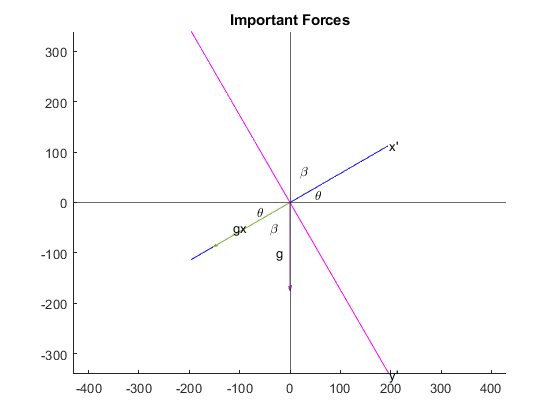

figure;
theta = 30;
gravity = 9.81;
mass = 20;

weight = gravity * mass;

X = linspace(-weight, weight);
y_prime_line = X .* -1/tand(theta);
x_prime_line = X .* tand(theta);

hold on;
plot(0, 5, "r-");
plot(X, y_prime_line, "Color", "magenta");
plot(X, x_prime_line, "Color", "blue");

quiver(0, 0, 0, -weight);
quiver(0, 0, -weight * cosd(theta), -weight * sind(theta));

text(-weight/7, -weight/2, "g");
text(-weight * cosd(theta) / 1.5, -weight * sind(theta) / 2, "g_{x}");

text(X(end), y_prime_line(end), "y'");
text(X(end), x_prime_line(end), "x'");
text(weight/4, weight/12, sprintf("\\theta"));
text(-weight/3, -weight/12, sprintf("\\theta"));
text(weight/10, weight/3, sprintf("\\beta"));
text(-weight/5, -weight/4, sprintf("\\beta"));
yline(0);
xline(0);

title("Important Forces");
axis equal;

$\theta =\arctan \left(f^{\prime } \left(x\_\textrm{pos}\right)\right)$ ver abajo para x_pos


$$\beta =90-\textrm{abs}\left(\theta \right)$$



$$g_x =-\textrm{sign}\left(\theta \right)*g*\cos \left(\beta \right)$$



$$\Delta x^{\prime } =v*\textrm{dt}+\frac{1}{2}*g_x *{\textrm{dt}}^2$$


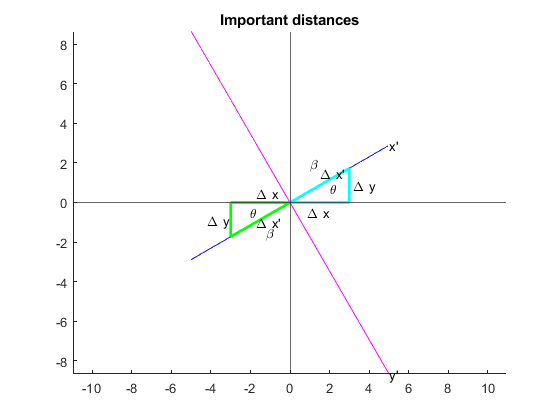

figure;
theta = 30;

X = linspace(-5, 5);
y_prime_line = X .* -1/tand(theta);
x_prime_line = X .* tand(theta);
x_prime_line_f = @(x) x .* tand(theta);

hold on;
plot(0, 5, "r-");
plot(X, y_prime_line, "Color", "magenta");
plot(X, x_prime_line, "Color", "blue");

plot([0 3], [0 x_prime_line_f(3)], "Color", "cyan", "LineWidth", 2);
plot([0 3], [0 0], "Color", "cyan", "LineWidth", 2);
plot([3 3], [0 x_prime_line_f(3)], "Color", "cyan", "LineWidth", 2);

plot([0 -3], [0 x_prime_line_f(-3)], "Color", "green", "LineWidth", 2);
plot([0 -3], [0 0], "Color", "green", "LineWidth", 2);
plot([-3 -3], [0 x_prime_line_f(-3)], "Color", "green", "LineWidth", 2);

text(1.5, 1.5, sprintf("\\Delta x'"));
text(x_prime_line_f(3)/2, -0.5, sprintf("\\Delta x"));
text(3.2, x_prime_line_f(3)/2, sprintf("\\Delta y"));

text(-1.7, -1, sprintf("\\Delta x'"));
text(-1.7, 0.5, sprintf("\\Delta x"));
text(-4.2, -x_prime_line_f(3)/2, sprintf("\\Delta y"));

text(2, 0.75, sprintf("\\theta"));
text(-2, -0.5, sprintf("\\theta"));
text(1, 2, sprintf("\\beta"));
text(-1.2, -1.5, sprintf("\\beta"));

text(X(end), y_prime_line(end), "y'");
text(X(end), x_prime_line(end), "x'");
yline(0);
xline(0);

title("Important distances");
legend({'Hacia arriba (velocidad +)', 'Hacia abajo (velocidad -)'});
axis equal;


$$\Delta x=\Delta x^{\prime } *\cos \left(\textrm{abs}\left(\theta \right)\right)$$



$$\Delta y=\Delta x^{\prime } *\sin \left(\textrm{abs}\left(\theta \right)\right)$$



$$\Delta x=\Delta x^{\prime } *\cos \left(\textrm{abs}\left(\theta \right)\right)*\textrm{sign}\left(v\right)$$



$$\Delta y=\textrm{sign}\left(v\right)*\textrm{sign}\left(\theta \right)*\Delta x^{\prime } *\sin \left(\textrm{abs}\left(\theta \right)\right)$$



$$x\_\textrm{pos}=x\_\textrm{pos}\_\textrm{anterior}+\Delta x$$



$$v^2 =\mathrm{sign}\left(v\right)*v_0^2 -\mathrm{sign}\left(v\right)*2*g*\Delta y-2*g*\mu_k *\Delta x$$



$$v^2 =\frac{\textrm{sign}\left(v\right)*v_0^2 *\left(1-\frac{\mu_k }{r_0 }\Delta x^{\prime } \right)-\textrm{sign}\left(v\right)*2*g*\Delta y-2*g*\mu_k *\Delta x}{1+\frac{\mu_k }{r}\Delta x^{\prime } }$$


vel = (sign(vel_initial) * vel_initial ^ 2 * (1 - (app.uk_coeff / radius_prev) * delta_x_prime) - sign(vel_initial) * 2 * app.gravity * delta_y - 2 * app.gravity * app.uk_coeff * delta_x) / (1 + (app.uk_coeff / radius) * delta_x_prime)

### Test

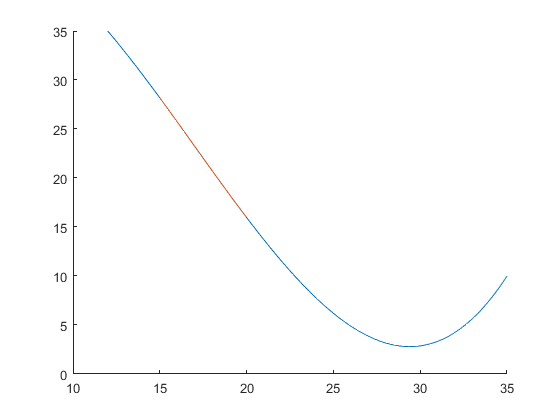

u_coefficients = [900500247072012281167/168331151358618085883904 -1432428825299147450741/5260348479956815183872 22524958276928016111259/10520696959913630367744 17217098719842417040971/438362373329734598656];
u_x_range = linspace(12, 35);
u_fn = polyval(u_coefficients, u_x_range);
u = @(x) 900500247072012281167/168331151358618085883904 .* x .^ 3 -1432428825299147450741/5260348479956815183872 .* x .^ 2 + 22524958276928016111259/10520696959913630367744 .* x + 17217098719842417040971/438362373329734598656;

figure;
hold on;
plot(u_x_range, u_fn);
line_range = linspace(15, 20);
plot(line_range, u(line_range));

Velocidad final, con fricción


$$v^2 ={v_o }^2 +2*g*\Delta y-2*g*\mu_k *\Delta x$$


delta_y = u(15) - u(20);
delta_x = 5;

v0 = 12;
g = 9.81;
uk = 0.01;

v = sqrt(v0 ^ 2 + 2 * g *delta_y - 2 * g * uk * delta_x)

v = 19.5580